## Output Data

We start our modeling tour by loading the output data (time-series data). The data contains one output, y, which is the angular position of the pendulum [rad]. The angle is zero when the pendulum is pointing downwards, and it is increasing anticlockwise. There are 1001 (simulated) samples of data points and the sample time is 0.1 seconds. The pendulum is affected by a constant gravity force, but no other exogenous force affects the motion of the pendulum. To investigate this situation, we create an IDDATA object:

clear all;
clf; clc;
loadSim

Loading file: D05_08_h05_Ed_Asbc_R01
Loading file: D05_08_h05_Ef_Ab_03H01_R01
Loading file: D05_08_h05_Ef_Asbc_R01
Loading file: D05_13_h05_Ef_An_R01
Loading file: D06_05_h05_Ea_An00H00_R01
Loading file: D06_05_h05_Eb_An00H00_R01
Loading file: D06_05_h05_Ed_As10H05_R01
Loading file: D06_05_h05_Ef_Ab05H02_R01
Loading file: D06_05_h05_Ef_Ab05H05_R01
Loading file: D06_05_h05_Ef_Ac05H0108_R01
Loading file: D06_05_h05_Ef_Ac08H0108_R01
Loading file: D06_05_h05_Ef_As03H02_R01
Loading file: D06_05_h05_Ef_As03H05_R01
Loading file: D06_05_h05_Ef_As03H10_R01
Loading file: D06_05_h05_Ef_As05H05_R01
Loading file: D06_05_h05_Ef_As07H02_R01
Loading file: D06_05_h05_Ef_As10H05_R01
Loading file: DC_bias
Elapsed time is 0.198732 seconds.
Data loaded


u_mean = mean(DC_bias.data(:,4));
y = D05_08_h05_Ed_Asbc_R01.data(:,3);
u = D05_08_h05_Ed_Asbc_R01.data(:,5);%-u_mean;
z = iddata(y, u, 0.05, 'Name', 'Motor');
z.OutputName = {'Flywheel angular velocity'};
z.OutputUnit = {'rad/s'};
z.InputName = {'Control Signal'};
z.Tstart = 0;
z.TimeUnit = 's';

FileName      = 'motor';        % File describing the model structure.
Order         = [1 1 1];             % Model orders [ny nu nx].

Jf = 2.3e-4;
k_t = 0.027;
k_e = 0.025;
R = 2.3;
tau_fd = 1.32e-6;

K1 = 80; %k_t;
K2 = k_t*k_e/R;
K3 = tau_fd/Jf;

Parameters    = [K1, K2, K3];   % Initial parameters. %Jf,c_u,c_v
InitialStates = 0;             % Initial initial states.
Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Flywheel angular velocity'};
nlgr.OutputUnit = {'rad/s'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Flywheel velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad/s'});
nlgr = setpar(nlgr, 'Name', {'K1' 'K2' 'K3'});
nlgr = setpar(nlgr, 'Unit', {'-' '-' '-'});
nlgr = setpar(nlgr, 'Minimum', {eps(0) eps(0) eps(0)});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {inf inf inf});   % All parameters > 0.

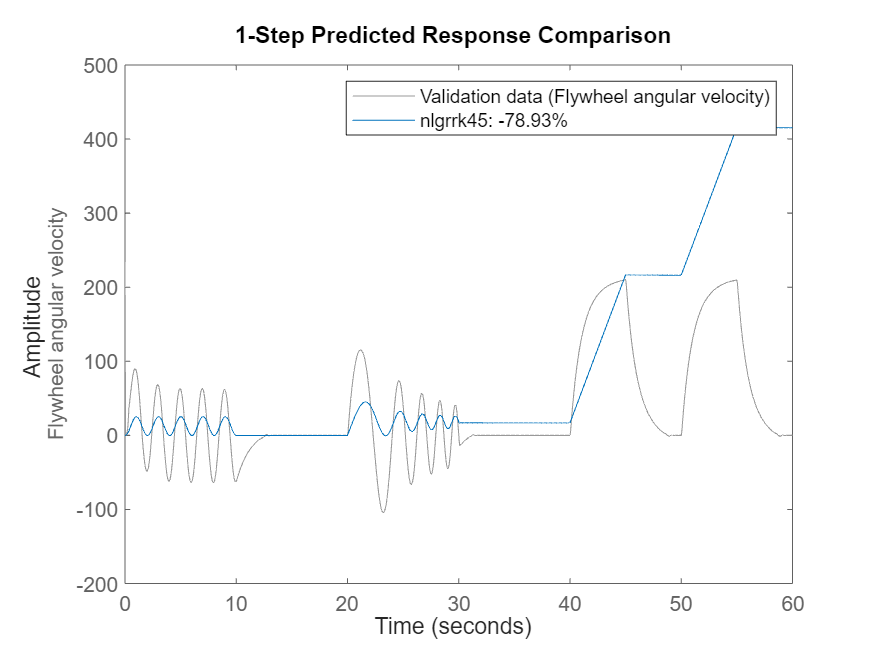


% C. Model computed with adaptive Runge-Kutta 45 ODE solver.
nlgrrk45 = nlgr;
nlgrrk45.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

figure(999);
compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

**Figure 3:** Comparison between true output and the simulated outputs of the three initial pendulum models.

As can be seen, the result with the Euler forward method (with a finer grid than what is used by default) differs significantly from the results obtained with the Runge-Kutta solvers. In this case, it turns out that the Euler forward solver produces a rather good result (in terms of model fit), whereas the outputs obtained with the Runge-Kutta solvers are a bit limited. However, this is somewhat deceiving, as will be evident later on, because the initial value of b, the viscous friction coefficient, is twice as large as in reality.

## Parameter Estimation

The gravitational constant, g, the length of the rod, l, and the mass of the bob, m, can easily be measured or taken from a table without estimation. However, this is typically not the case with friction coefficients, which often must be estimated. We therefore fix the former three parameters to g = 9.81, l = 1, and m = 1, and consider only b as a free parameter:

nlgrrk45 = setpar(nlgrrk45, 'Fixed', {false false false});

We finally use the Runge-Kutta 45 solver (ode45).

opt = nlgreyestOptions('Display', 'on');
opt.SearchOptions.StepTolerance = 1e-3;
trk45 = clock;
nlgrrk45 = nlgreyest(z, nlgrrk45, opt);   % Perform parameter estimation.
trk45 = etime(clock, trk45);
figure(9999);

However, this does not mean that the simulated outputs differ that much from the actual output, because the errors produced by the different differential equation solvers are typically accounted for in the estimation procedure. This is a fact that readily can be seen by simulating the three estimated pendulum models.

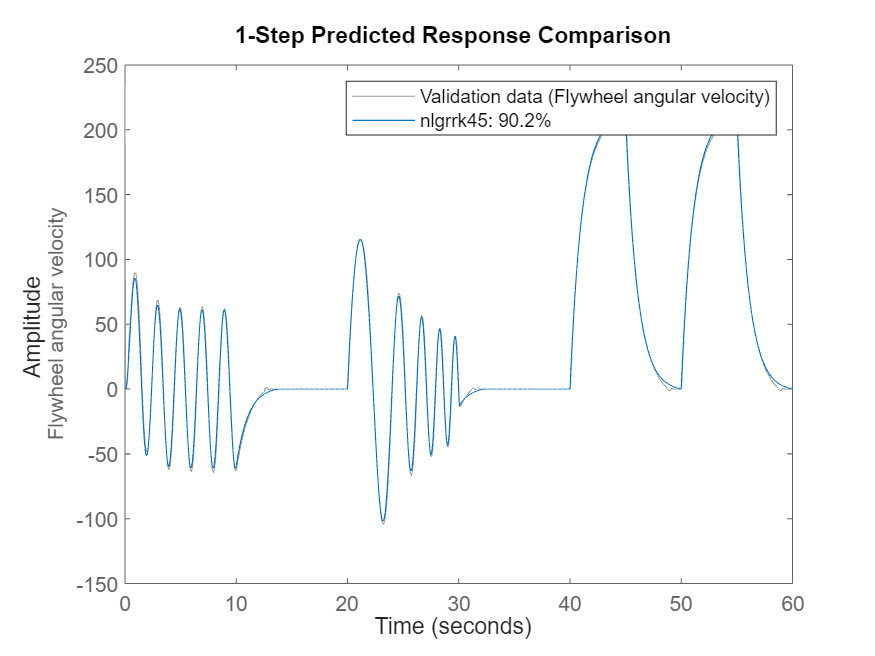

compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45.Parameters

ans = 3×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


**Figure 4:** Comparison between true output and the simulated outputs of the three estimated pendulum models.

As expected given this figure, the Final Prediction Error (FPE) criterion values of these models are also rather close to each other:

fpe(nlgrrk45);

   53.5117




nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'motor' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p3)
    y(t) = H(t, u(t), x(t), p1, ..., p3) + e(t)

 with 1 input(s), 1 state(s), 1 output(s), and 3 free parameter(s) (out of 3).

Status:                                                                      
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Motor".
Fit to estimation data: 90.2%                                                
FPE: 53.51, MSE: 53.24                                                       

Model Properties


ans = 3×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


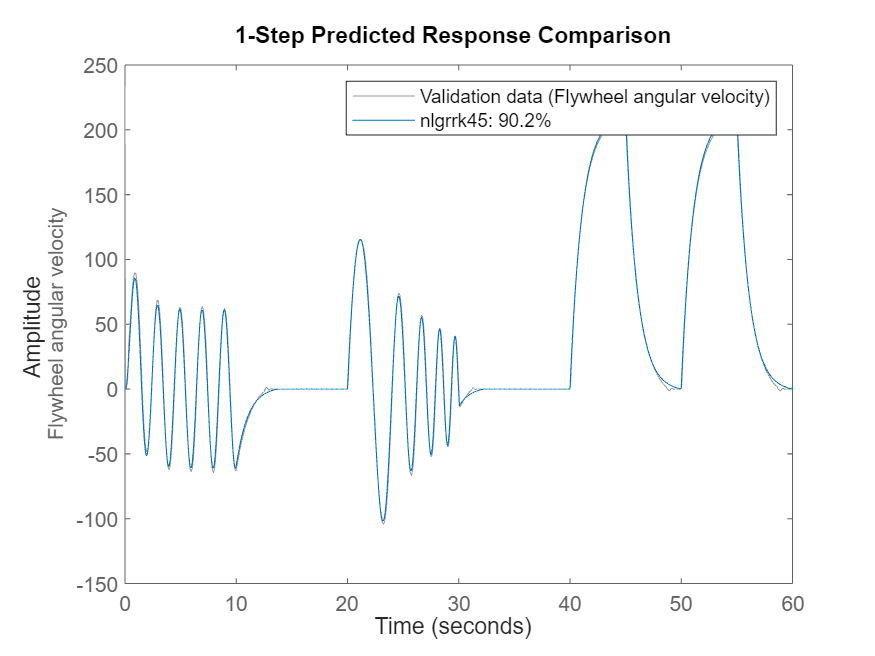


for i = 1:1
    % if i==1
    %     y = D06_05_h05_Ef_As03H02_R01.data(:,3);
    %     u = D06_05_h05_Ef_As03H02_R01.data(:,4);
    % elseif i==2
    %     y = D06_05_h05_Ef_As05H05_R01.data(:,3);
    %     u = D06_05_h05_Ef_As05H05_R01.data(:,4);
    % elseif i==3
    %     y = D06_05_h05_Ef_As07H02_R01.data(:,3);
    %     u = D06_05_h05_Ef_As07H02_R01.data(:,4);
    % elseif i==4
    %     y = D06_05_h05_Ef_As03H10_R01.data(:,3);
    %     u = D06_05_h05_Ef_As03H10_R01.data(:,4);
    % else
    %     y = D06_05_h05_Ef_As03H05_R01.data(:,3);
    %     u = D06_05_h05_Ef_As03H05_R01.data(:,4);
    % end
    % 
    % z = iddata(y, u, 0.05, 'Name', 'Motor');
    % z.OutputName = {'Flywheel angular velocity'};
    % z.OutputUnit = {'rad/s'};
    % z.InputName = {'Control Signal'};
    % z.Tstart = 0;
    % z.TimeUnit = 's';
    
    % nlgrrk45 = pem(z,nlgrrk45, opt)
    nlgrrk45 = nlgreyest(z,nlgrrk45, opt)

    nlgrrk45.Parameters
    figure(i),clf;
        compare(z, nlgrrk45, 1, ...
        compareOptions('InitialCondition', 'model'));
end